clear all
close all

% Valores nominales de los parámetros
m_nominal = 3;
c_nominal = 0.5;
k_nominal = 2;

% Incertidumbre del 10%
% %Crear un parámetro real incierto con un valor nominal cuyo valor puede aumentar o disminuir en un 10%
m = ureal('m', m_nominal, 'Percentage', 10); 
c = ureal('c', c_nominal, 'Percentage', 10);
k = ureal('k', k_nominal, 'Percentage', 10);

%
get(m)

    NominalValue: 3
            Mode: 'Percentage'
           Range: [2.700000000000000 3.300000000000000]
       PlusMinus: [-0.300000000000000 0.300000000000000]
      Percentage: [-10 10]
    AutoSimplify: 'basic'
            Name: 'm'




% Número de muestras
num_samples = 30;

% Configuración de la simulación
t = 0:0.01:40;  % Tiempo de simulación

% Realizar el muestreo
m_samples = usample(m, num_samples);
c_samples = usample(c, num_samples);
k_samples = usample(k, num_samples);


% Inicializar matrices para almacenar las respuestas
x1_responses = zeros(num_samples, length(t));
x2_responses = zeros(num_samples, length(t));


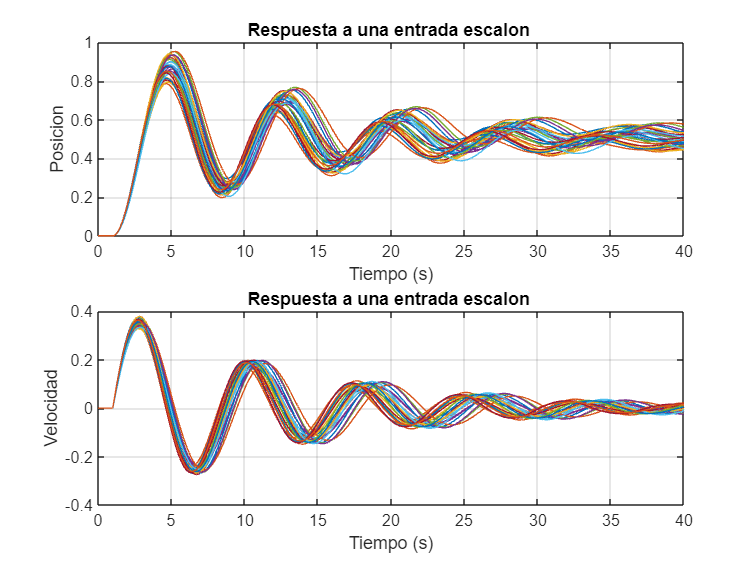

% Simular cada sistema
for i = 1:num_samples

    % Asignar valores de los parámetros al modelo en Simulink
    set_param('t7_videoclase2_masa_resorte_amortiguador/m', 'Gain', num2str(1/m_samples(i)));
    set_param('t7_videoclase2_masa_resorte_amortiguador/c', 'Gain', num2str(c_samples(i)));
    set_param('t7_videoclase2_masa_resorte_amortiguador/k', 'Gain', num2str(k_samples(i)));

    % Ejecutar la simulación
    simOut = sim('t7_videoclase2_masa_resorte_amortiguador', 'StopTime', num2str(t(end)));

    t = simOut.tout;
    x1_responses(i, :) = simOut.xout(:, 1);
    x2_responses(i, :) = simOut.xout(:, 2);
end

% Mostrar resultados
figure;
subplot(2,1,1);
plot(t, x1_responses);
title('Respuesta a una entrada escalon ');
xlabel('Tiempo (s)');
ylabel('Posicion');
grid on;
subplot(2,1,2);
plot(t, x2_responses);
title('Respuesta a una entrada escalon ');
xlabel('Tiempo (s)');
ylabel('Velocidad');
grid on;